## Aufgabe 3

### Sekundenpendel Analytisch:

### DGL:


$$\ddot{\varphi}(t) + \frac{g}{L}\varphi(t) = 0
$$


### Lösung:


$$\varphi (t)=\varphi_0 \cos (\omega t),$$


### Kreisfrequenz:


$$\omega = \sqrt{\frac{g}{L}}$$


### Periodendauer einer Schwingung:


$$T = \frac{2\pi}{\omega} = 2\pi\sqrt{\frac{L}{g}}$$


### Periodendauer eines Sekundenpendels:


$$T = 2\,\mathrm{s}$$


### Einsetzen:


$$2 = 2\pi\sqrt{\frac{L}{g}}$$


### Umstellen auf Pendellänge:


$$L = \frac{g}{\pi^2}$$


format long
g = 9.81;
L_analytisch = g/pi^2;
fprintf('Pendellänge Analytisch: %.15f m\n', L_analytisch)

Pendellänge Analytisch: 0.993960811531334 m


### 
$$L \approx 0.994\,\mathrm{m}$$


### Sekundenpendel numerisch:

% Zur Bestimmung der Pendellänge wird mit fzero die Länge bestimmt,
% für welche die Periodendauer des Pendels genau 2 s beträgt
format short
phi0 = 0.01;   % Startwinkel (rad)
Periodendauer = 2; %Periodendauer (sec)

% Länge des Sekundenpendels bestimmen
L_numerisch = fzero(@(L) Perioden_Fehlerfunktion(L,phi0, Periodendauer), [0.5 2]);

fprintf('Pendellänge Numerisch: %.15f m\n', L_numerisch);

Pendellänge Numerisch: 0.993617133044021 m



%Absoluter Fehler und Realtiver Fehler:

Fehler_Absolut = abs(L_numerisch - L_analytisch);
fprintf('Absoluter Fehler: %.5f m\n', Fehler_Absolut);

Absoluter Fehler: 0.00034 m



Fehler_Relativ = Fehler_Absolut/L_analytisch;
Fehler_Relativ_Prozent = Fehler_Relativ*100;
fprintf('Relativer Fehler: %.5f bzw. %.5f Prozent \n', Fehler_Relativ, Fehler_Relativ_Prozent);

Relativer Fehler: 0.00035 bzw. 0.03458 Prozent 


### Länge des Sekundenpendels in Abhängigkeit von der Startauslenkung:

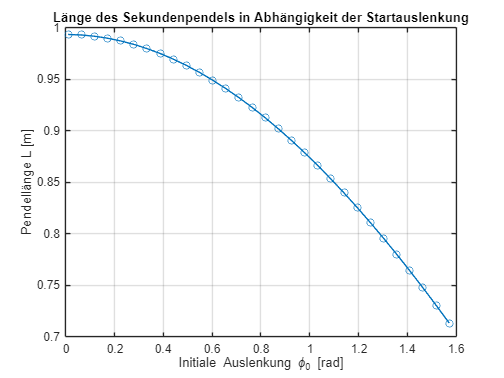

%Für den Plot der Länge in Abhängigkeit der Auslenkung wird mit einer
%Schleife die Initiale Auslenkung variiert und anschließend die selbe
%Routine wie für das Sekundenpendel durchgeführt

phi0_vec = linspace(phi0, pi/2, 30);   % Startauslenkung in rad
L_phi = zeros(size(phi0_vec));

for k = 1:length(phi0_vec)
    phi0 = phi0_vec(k);

    % Sekundenpendel-Länge für diese Auslenkung
    L_phi(k) = fzero(@(L) Perioden_Fehlerfunktion(L, phi0, Periodendauer), [0.5 2]);
end

figure;
plot(phi0_vec, L_phi, '-o');
xlabel('Initiale Auslenkung \phi_0 [rad]');
ylabel('Pendellänge L [m]');
grid on;
title('Länge des Sekundenpendels in Abhängigkeit der Startauslenkung');